% Q1: 
% Specify K, mu and covm:
K = 100;
% mu has D values, one per dimension
mu = [400, 500, 600];
covm = [10 2 1;
        2 5 3;
        1 3 8];

% Generate random Gaussian data
rgdata = genGauss(K,mu,covm);

% Q2: Testing and Verification
% The sample mean should be close to 'mu'
sample_mean = mean(rgdata);

% The sample covariance should be close to 'covm'
sample_cov = cov(rgdata);

% Display results to the command window
disp('--- Target Mean ---'); disp(mu);

--- Target Mean ---
   400   500   600



disp('--- Sample Mean ---'); disp(sample_mean);

--- Sample Mean ---
  400.4536  499.9329  600.1534



disp('--- Target Covariance ---'); disp(covm);

--- Target Covariance ---
    10     2     1
     2     5     3
     1     3     8



disp('--- Sample Covariance ---'); disp(sample_cov);

--- Sample Covariance ---
    8.1660    2.5394    1.0300
    2.5394    6.7634    3.5112
    1.0300    3.5112    9.5756



Q3: The function randn() produces K data points using a random sample from a Gaussian distribution. Since it's a sample, it will contain sampling error from the true distribution. Because of this, the sample mean will not be exactly 0 and the sample covariance will not be exactly the identity matrix. This error will persist through the whitening transformation, resulting in a covariance matrix that doesn't exactly match our specified covm.

Q4: In order to ensure the sampling error is removed, we can apply the whitening transform to the sample data itself. We adjust the sample mean to 0 and the sample's covariance matrix to the identity matrix first (via the whitening transformation), then we apply the inverse whitening from Q1 above to get data with our prescribed mean and covariance.

% Get a whitened sample
dims = length(mu); % Set dimensions based on the mean vector
X_w = whitenData(K, dims); % Get a whitened sample

% Verify that the mean of the whitened data is zero
whitened_mean = mean(X_w);
% Verify that the covariance of the whitened data is the identity matrix
whitened_cov = cov(X_w);

% Set the desired mean and covariance for class A, B and C
mu_a = [0, 4, 7];
mu_b = [10, 5, 5];
mu_c = [-2, -5, -5];

covm_a = [6.5 2.1651 1.25;
    2.1651 5.125 2.3816;
    1.25 2.3816 2.375];
covm_b = [3.0184 0.4331 -1.4481;
    0.4331 0.9436 -0.6456;
    -1.4481 -0.6456 1.288];
covm_c = [6.8928 -1.375 3.1945;
    -1.375 3.3572 0.6945;
    3.1945 0.6945 3.75];

% Inverse whiten to get 1000 data points with the above mean/covariance
K = 1000;
X_a = genExactGauss(K,mu_a,covm_a);
X_b = genExactGauss(K,mu_b,covm_b);
X_c = genExactGauss(K,mu_c,covm_c);

% Verify means
disp('--- Mean Class A ---'); disp(mean(X_a));

--- Mean Class A ---
    0.0000    4.0000    7.0000



disp('--- Mean Class B ---'); disp(mean(X_b));

--- Mean Class B ---
   10.0000    5.0000    5.0000



disp('--- Mean Class C ---'); disp(mean(X_c));

--- Mean Class C ---
   -2.0000   -5.0000   -5.0000



% Verify covariance matrices
disp('--- Covariance Class A ---'); disp(cov(X_a));

--- Covariance Class A ---
    6.5000    2.1651    1.2500
    2.1651    5.1250    2.3816
    1.2500    2.3816    2.3750



disp('--- Covariance Class B ---'); disp(cov(X_b));

--- Covariance Class B ---
    3.0184    0.4331   -1.4481
    0.4331    0.9436   -0.6456
   -1.4481   -0.6456    1.2880



disp('--- Covariance Class C ---'); disp(cov(X_c));

--- Covariance Class C ---
    6.8928   -1.3750    3.1945
   -1.3750    3.3572    0.6945
    3.1945    0.6945    3.7500



Q5: We compare our handmade functions with MATLAB's mvnrnd function.

Xalt_a = mvnrnd(mu_a, covm_a, K);
Xalt_b = mvnrnd(mu_b, covm_b, K);
Xalt_c = mvnrnd(mu_c, covm_c, K);

% Print means
disp('--- Mean Class A with mvnrnd ---'); disp(mean(Xalt_a));

--- Mean Class A with mvnrnd ---
    0.0897    3.9362    6.9662



disp('--- Mean Class B with mvnrnd ---'); disp(mean(Xalt_b));

--- Mean Class B with mvnrnd ---
    9.9623    4.9777    5.0443



disp('--- Mean Class C with mvnrnd ---'); disp(mean(Xalt_c));

--- Mean Class C with mvnrnd ---
   -2.0105   -4.9357   -4.9699



% Print covariance matrices
disp('--- Covariance Class A with mvnrnd ---'); disp(cov(Xalt_a));

--- Covariance Class A with mvnrnd ---
    5.9466    2.0933    1.1063
    2.0933    4.7432    2.1199
    1.1063    2.1199    2.2092



disp('--- Covariance Class B with mvnrnd ---'); disp(cov(Xalt_b));

--- Covariance Class B with mvnrnd ---
    2.7739    0.3196   -1.2470
    0.3196    0.8720   -0.5445
   -1.2470   -0.5445    1.1440



disp('--- Covariance Class C with mvnrnd ---'); disp(cov(Xalt_c));

--- Covariance Class C with mvnrnd ---
    6.8590   -1.4005    2.9615
   -1.4005    3.3997    0.7863
    2.9615    0.7863    3.7425



The above means and covariances generated using mvnrnd are close but not exactly equal to the means and covariance matrices we prescribed. This is because, as we found in Q1 to Q3 above, mvnrnd is taking a random sample from the Gaussian distribution we prescribe, but is leaving the sample error in place. In Q4, we applied the whitening transformation to remove the sample error, giving us a sample with exactly the same mean and covariance as the original distribution; it's important to realize that mvnrnd doesn't do this!

Bayesian Optimal decision boundaries are based on the true underlying distribution. Therefore, when visualizing such a decision boundary, we can't use noisy data with sampling error; instead, we need to pre-whiten the data so that the sample mean and covariance match the true mean and covariance.

% Functions

% Q1: A function  to create K samples of D-dimensional Gaussian data
% with specified mean, mu and covariance matrix, covm
function X_m = genGauss(K,mu,covm)
    % Get length of mu
    lenMu = length(mu);
    % Get K random lenMu-dimensional data points (perfect sphere)
    data =  randn(K,lenMu);
    % get the eigendecomposition of covm
    [V, D] = eig(covm);
    % Stretch (D) and rotate (V) the data so it has covariance, covm, then
    % shift it to match the mean, mu -> K x 3
    X_m = (data * sqrt(D) * V') + mu(:)'; % mu must be a row vector
end

% Q4: A function that applies the whitening transformation to a sample of K
% data points randomly drawn from a Gaussian (0,1) distribution.
function X_w = whitenData(K, dims)
    % Generate a random sample from a Gaussian (0,1)
    data = randn(K, dims);
    % Center the data
    data = data - mean(data);
    % Get the eigendecomposition of the covariance matrix
    [V, D] = eig(cov(data));
    % Apply the whitening transformation
    X_w = data * V * inv(sqrt(D));
end

% Q4: We update our function from Q1 so that it uses pre-whitened data
% to perfectly match the mean/covariance
function X_m = genExactGauss(K,mu,covm)
    % Get length of mu
    lenMu = length(mu);
    % Get a whitened sample
    data = whitenData(K, lenMu);
    % get the eigendecomposition of covm
    [V, D] = eig(covm);
    % Stretch (D) and rotate (V) the data so it has covariance, covm, then
    % shift it to match the mean, mu -> K x 3
    X_m = (data * sqrt(D) * V') + mu(:)'; % mu must be a row vector
end

6. Use matlab’s ellipsoid() function to create contour intervals for Classes A, B, and C at one, two, and three standard deviations from µA, µB, and µC and also on the same plot the principal axes of each generated Gaussian contour ellipses using matlab’s line() function.

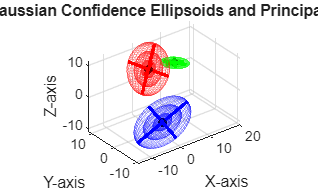


% Setup the figure
figure;
hold on;
grid on;
axis equal;
view(3); % View in 3D space
xlabel('X-axis'); ylabel('Y-axis'); zlabel('Z-axis');
title('3D Gaussian Confidence Ellipsoids and Principal Axes');

% Colors for each class
colors = {'r', 'g', 'b'};

% Plot for each class
plotClassEllipsoids(mu_a, covm_a, colors{1});
plotClassEllipsoids(mu_b, covm_b, colors{2});
plotClassEllipsoids(mu_c, covm_c, colors{3});

hold off;


function plotClassEllipsoids(mu, covm, color)
    % 1. Get eigenvalues (D) and eigenvectors (V)
    [V, D] = eig(covm);
    
    % The lengths of the semi-axes are the square roots of the eigenvalues
    % (which represent 1 standard deviation along the principal axes)
    radii_1std = sqrt(diag(D))';
    
    % Define the standard deviations we want to plot
    stdDevs = [1, 2, 3];
    
    % Loop through 1, 2, and 3 standard deviations
    for sd = stdDevs
        % Scale the base radii by the standard deviation level
        current_radii = radii_1std * sd;
        
        % Generate a standard axis-aligned ellipsoid at the origin
        % syntax: ellipsoid(xc, yc, zc, xr, yr, zr, n)
        [X, Y, Z] = ellipsoid(0, 0, 0, current_radii(1), current_radii(2), current_radii(3), 30);
        
        % Rotate and translate the ellipsoid points
        % Pack points into an N x 3 matrix
        pts = [X(:), Y(:), Z(:)];
        
        % Apply rotation (V) and shift to the mean (mu)
        rotated_pts = (pts * V') + mu;
        
        % Reshape back into surface grids for plotting
        X_rot = reshape(rotated_pts(:,1), size(X));
        Y_rot = reshape(rotated_pts(:,2), size(Y));
        Z_rot = reshape(rotated_pts(:,3), size(Z));
        
        % Plot the ellipsoid surface with transparency (Alpha)
        mesh(X_rot, Y_rot, Z_rot, 'FaceColor', 'none', 'EdgeColor', color, 'EdgeAlpha', 0.2);
    end
    
    % 2. Plot the Principal Axes (drawn out to 3 standard deviations)
    for d = 1:3
        % Direction vector of the principal axis
        axis_direction = V(:, d)'; 
        % Half-length of the axis at 3 standard deviations
        half_length = radii_1std(d) * 3; 
        
        % Calculate start and end points for the line
        p_start = mu - half_length * axis_direction;
        p_end = mu + half_length * axis_direction;
        
        % Draw the principal axis line using matlab's line() function
        line([p_start(1), p_end(1)], ...
             [p_start(2), p_end(2)], ...
             [p_start(3), p_end(3)], ...
             'Color', color, 'LineWidth', 2);
    end
    
    % Plot the center mean point
    plot3(mu(1), mu(2), mu(3), 'k.', 'MarkerSize', 15);
end

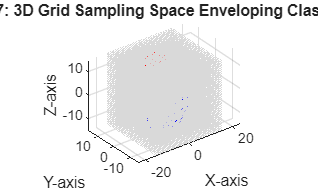

% question 7

Vaxis = [-15, 15];

Num = 40; % 40 points along X, 40 along Y, 40 along Z

grid_points = vol3D(Vaxis, Num);

% --- QUESTION 7: Generating and Visualizing the 3D Grid Space ---

% 1. Define bounds that wrap around all classes (-15 to 15 on all axes)
Vaxis = [-15, 15]; 
Num = 40; % Generates 40^3 = 64,000 regular grid points

% 2. Call your custom vol3D function
grid_points = vol3D(Vaxis, Num);

% 3. Overlay the grid onto your existing Question 6 figure
hold on;

% Plot the grid points as a light gray background cloud
% grid_points(:,1) is X, grid_points(:,2) is Y, grid_points(:,3) is Z
plot3(grid_points(:,1), grid_points(:,2), grid_points(:,3), ...
      '.', 'Color', [0.85 0.85 0.85], 'MarkerSize', 2);

% Push the grid points to the background visual layer so ellipsoids stay clear
grid on;
title('Question 7: 3D Grid Sampling Space Enveloping Class Ellipsoids');
hold off;

% question 8

covm_a_inv = inv(covm_a)

covm_a_inv =     0.1806   -0.0601   -0.0347
   -0.0601    0.3854   -0.3548
   -0.0347   -0.3548    0.7952


covm_b_inv = inv(covm_b)

covm_b_inv =     0.7987    0.3771    1.0870
    0.3771    1.7910    1.3217
    1.0870    1.3217    2.6610


covm_c_inv = inv(covm_c)

covm_c_inv =     0.3363    0.2048   -0.3244
    0.2048    0.4345   -0.2550
   -0.3244   -0.2550    0.5902



covm_a_det = det(covm_a)

covm_a_det = 35.9991

covm_b_det = det(covm_b)

covm_b_det = 0.9998

covm_c_det = det(covm_c)

covm_c_det = 36.0017


class_a_points = grid_points - mu_a

class_a_points =   -15.0000  -19.0000  -22.0000
  -15.0000  -19.0000  -21.2308
  -15.0000  -19.0000  -20.4615
  -15.0000  -19.0000  -19.6923
  -15.0000  -19.0000  -18.9231
  -15.0000  -19.0000  -18.1538
  -15.0000  -19.0000  -17.3846
  -15.0000  -19.0000  -16.6154
  -15.0000  -19.0000  -15.8462
  -15.0000  -19.0000  -15.0769
  -15.0000  -19.0000  -14.3077
  -15.0000  -19.0000  -13.5385
  -15.0000  -19.0000  -12.7692
  -15.0000  -19.0000  -12.0000
  -15.0000  -19.0000  -11.2308


class_b_points = grid_points - mu_b

class_b_points =   -25.0000  -20.0000  -20.0000
  -25.0000  -20.0000  -19.2308
  -25.0000  -20.0000  -18.4615
  -25.0000  -20.0000  -17.6923
  -25.0000  -20.0000  -16.9231
  -25.0000  -20.0000  -16.1538
  -25.0000  -20.0000  -15.3846
  -25.0000  -20.0000  -14.6154
  -25.0000  -20.0000  -13.8462
  -25.0000  -20.0000  -13.0769
  -25.0000  -20.0000  -12.3077
  -25.0000  -20.0000  -11.5385
  -25.0000  -20.0000  -10.7692
  -25.0000  -20.0000  -10.0000
  -25.0000  -20.0000   -9.2308


class_c_points = grid_points - mu_c

class_c_points =   -13.0000  -10.0000  -10.0000
  -13.0000  -10.0000   -9.2308
  -13.0000  -10.0000   -8.4615
  -13.0000  -10.0000   -7.6923
  -13.0000  -10.0000   -6.9231
  -13.0000  -10.0000   -6.1538
  -13.0000  -10.0000   -5.3846
  -13.0000  -10.0000   -4.6154
  -13.0000  -10.0000   -3.8462
  -13.0000  -10.0000   -3.0769
  -13.0000  -10.0000   -2.3077
  -13.0000  -10.0000   -1.5385
  -13.0000  -10.0000   -0.7692
  -13.0000  -10.0000         0
  -13.0000  -10.0000    0.7692


mul_a = class_a_points * covm_a_inv

mul_a =    -0.8018    1.3856  -10.2306
   -0.8285    1.1126   -9.6189
   -0.8552    0.8397   -9.0073
   -0.8819    0.5667   -8.3956
   -0.9086    0.2938   -7.7840
   -0.9353    0.0208   -7.1723
   -0.9620   -0.2521   -6.5607
   -0.9887   -0.5251   -5.9490
   -1.0155   -0.7981   -5.3373
   -1.0422   -1.0710   -4.7257
   -1.0689   -1.3440   -4.1140
   -1.0956   -1.6169   -3.5024
   -1.1223   -1.8899   -2.8907
   -1.1490   -2.1628   -2.2791
   -1.1757   -2.4358   -1.6674


mul_b = class_b_points * covm_b_inv

mul_b =   -49.2489  -71.6815 -106.8284
  -48.4128  -70.6648 -104.7814
  -47.5766  -69.6481 -102.7345
  -46.7405  -68.6314 -100.6876
  -45.9043  -67.6147  -98.6407
  -45.0682  -66.5980  -96.5938
  -44.2321  -65.5813  -94.5469
  -43.3959  -64.5647  -92.5000
  -42.5598  -63.5480  -90.4531
  -41.7236  -62.5313  -88.4061
  -40.8875  -61.5146  -86.3592
  -40.0514  -60.4979  -84.3123
  -39.2152  -59.4812  -82.2654
  -38.3791  -58.4645  -80.2185
  -37.5429  -57.4478  -78.1716


mul_c = class_c_points * covm_c_inv

mul_c =    -3.1761   -4.4584    0.8647
   -3.4257   -4.6545    1.3187
   -3.6752   -4.8507    1.7727
   -3.9248   -5.0468    2.2268
   -4.1743   -5.2429    2.6808
   -4.4239   -5.4391    3.1349
   -4.6734   -5.6352    3.5889
   -4.9230   -5.8313    4.0429
   -5.1725   -6.0275    4.4970
   -5.4221   -6.2236    4.9510
   -5.6716   -6.4197    5.4050
   -5.9212   -6.6159    5.8591
   -6.1707   -6.8120    6.3131
   -6.4203   -7.0081    6.7671
   -6.6698   -7.2043    7.2212



row_sum_a = sum(mul_a .* class_a_points,2)

row_sum_a =   210.7740
  195.5051
  181.1772
  167.7903
  155.3445
  143.8397
  133.2758
  123.6530
  114.9712
  107.2304
  100.4306
   94.5719
   89.6541
   85.6774
   82.6416


row_sum_b = sum(mul_b .* class_b_points,2)

row_sum_b = 1.0e+03 *

    4.8014
    4.6386
    4.4790
    4.3225
    4.1692
    4.0190
    3.8720
    3.7281
    3.5874
    3.4498
    3.3154
    3.1841
    3.0559
    2.9310
    2.8091


row_sum_c = sum(mul_c .* class_c_points,2)

row_sum_c =    77.2270
   78.9065
   81.2845
   84.3611
   88.1362
   92.6097
   97.7819
  103.6525
  110.2216
  117.4893
  125.4555
  134.1201
  143.4834
  153.5451
  164.3053



g_a = -0.5 * row_sum_a -0.5 * log(covm_a_det)+log(1/3);
g_b = -0.5 * row_sum_b - 0.5 * log(covm_b_det) + log(1/3);
g_c = -0.5 * row_sum_c - 0.5 * log(covm_c_det) + log(1/3);

[~, assigned_class] = max([g_a, g_b, g_c], [], 2)

assigned_class =      3
     3
     3
     3
     3
     3
     3
     3
     3
     1
     1
     1
     1
     1
     1
